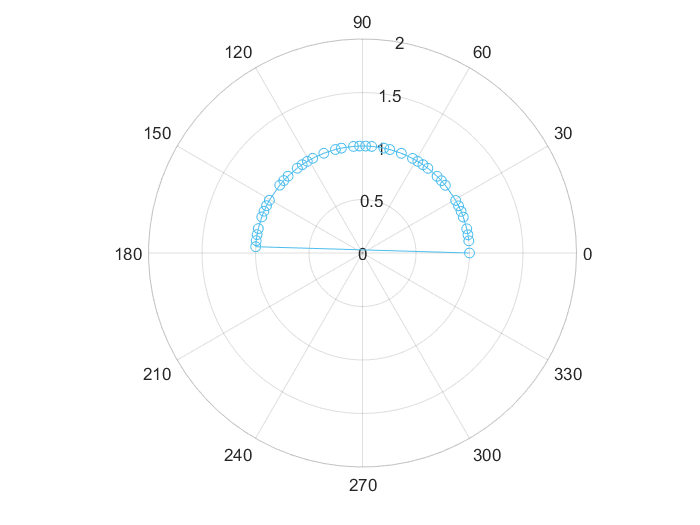

characters = split("abcdefghijklmnopqrstuvwxyz", "");

base1 = 13;
l = 25;

letters = sym(zeros(l, 1));

for i = 0:length(letters)
    letters(i+1) = (pi * i) / base1;
end

letters;

%%

base2 = 55;
factors = factor(base2);
prime_letters = sym(zeros(base2, 1));

index = 1;
for i = 2:base2
    skip = false;
    for f = 1:length(factors)
        if mod(i, factors(f)) == 0
            skip = true;
        end
    end
    
    if skip ~= true
        prime_letters(index) = (3.14 * i) / base2;
        index = index + 1;
    end
end

polarplot(prime_letters, ...
    ones(length(prime_letters)), '-o')